# AAE 567 HW3 Problem5

% Housekeeping commands
clear all; close all; clc;
set(groot, 'defaulttextinterpreter','latex');
set(groot, 'defaultAxesTickLabelInterpreter','latex');
set(groot, 'defaultLegendInterpreter','latex');

% Define given vector
t = linspace(0, pi, 10000)

t =          0    0.0003    0.0006    0.0009    0.0013    0.0016    0.0019    0.0022    0.0025    0.0028    0.0031    0.0035    0.0038    0.0041    0.0044    0.0047    0.0050    0.0053    0.0057    0.0060    0.0063    0.0066    0.0069    0.0072    0.0075    0.0079    0.0082    0.0085    0.0088    0.0091    0.0094    0.0097    0.0101    0.0104    0.0107    0.0110    0.0113    0.0116    0.0119    0.0123    0.0126    0.0129    0.0132    0.0135    0.0138    0.0141    0.0145    0.0148    0.0151    0.0154


y = sin(t);

% Define the Vandermonde matrix
V = fliplr(vander(t));
V = V(:, 1:6);

ahat = pinv(V)*y';
error2 = norm(y)^2 - dot(ahat, V'*y');
error = sqrt(error2);

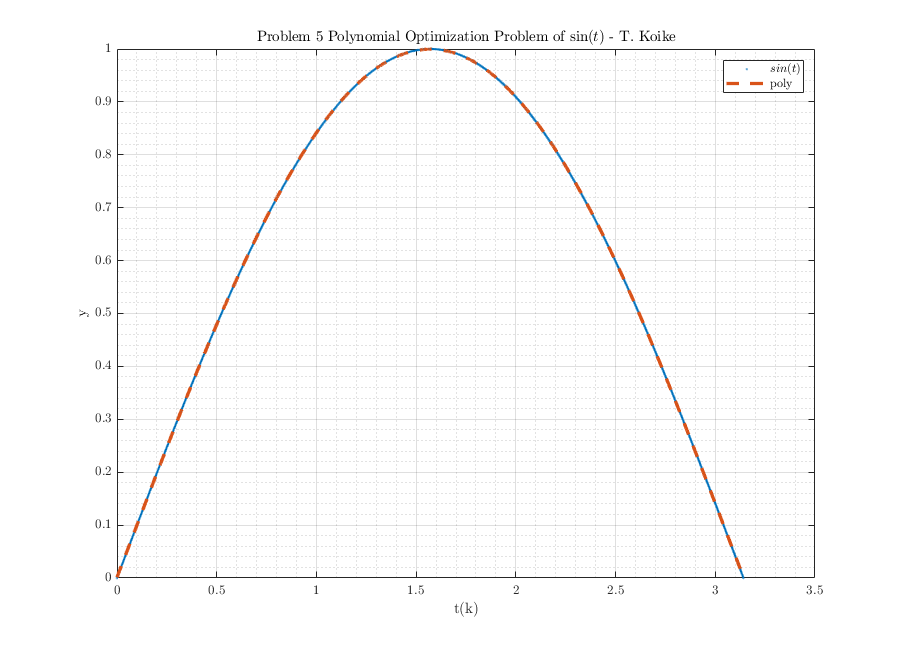

% Plotting
fig = figure("Renderer","painters", "Position",[60 60 900 650]);
    plot(t, y, '.', "MarkerSize", 3)
    hold on; grid on; box on; grid minor;
    plot(t, polyval(flip(ahat)', t), '--', 'LineWidth',2.5)
    title("Problem 5 Polynomial Optimization Problem of $\sin (t)$ - T. Koike")
    xlabel('t(k)')
    ylabel('y')
    legend('$sin(t)$', 'poly')
saveas(fig,"hw3_p5_sinDiscretePolyOpt.png")